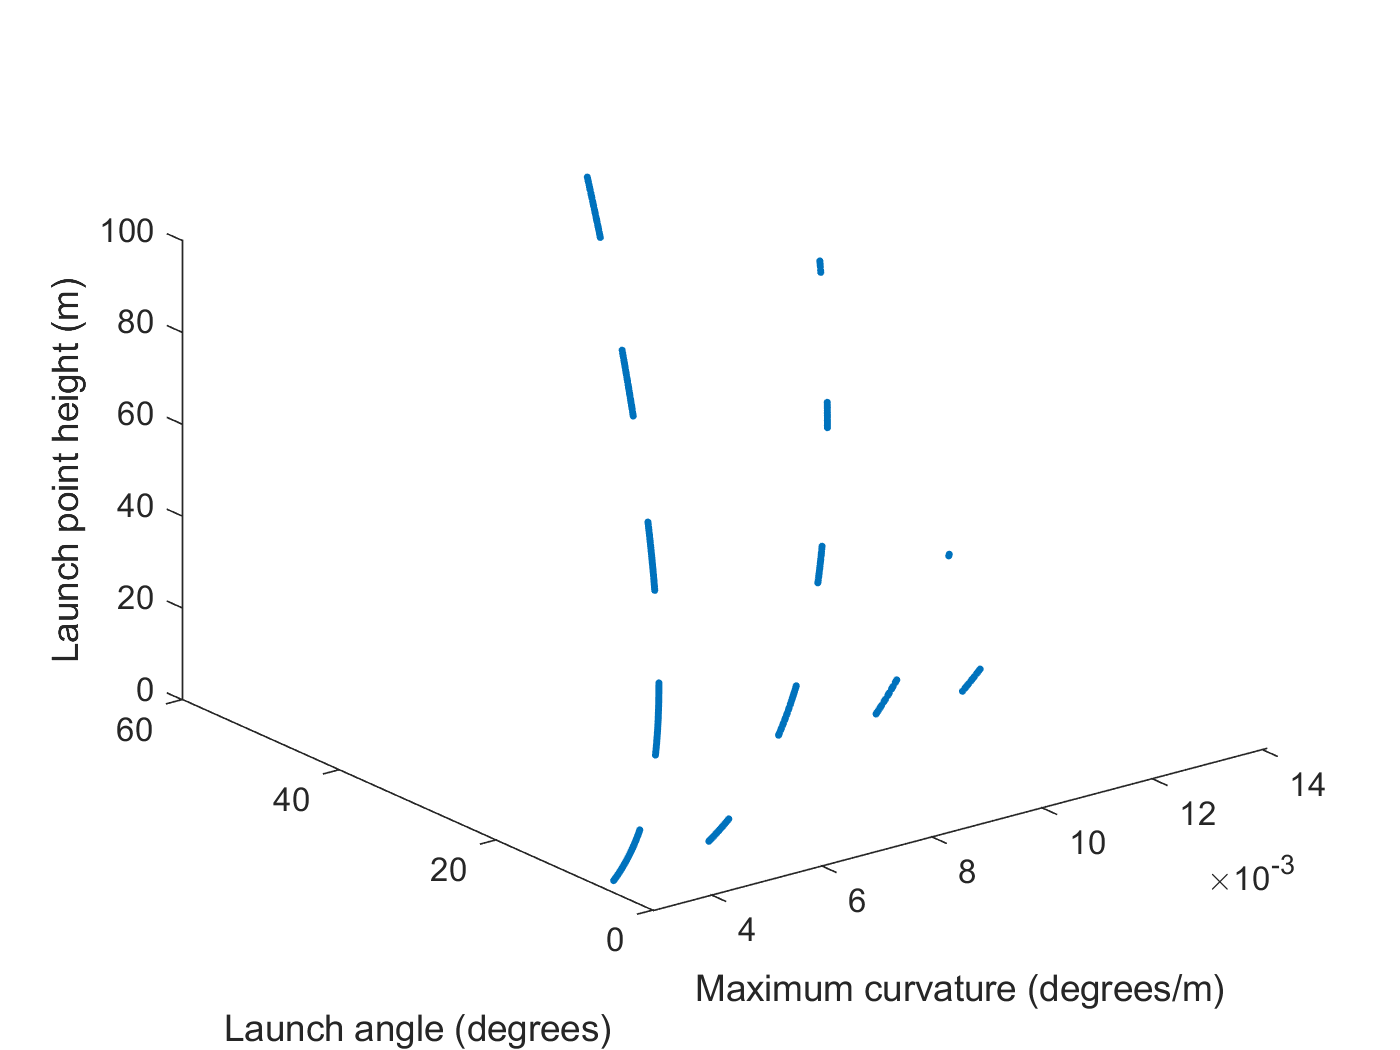

% Run this file to perform Subsystem 4 optimisation

% Sampling feasible launch track geometries. This might take several
% minutes
smoothLaunchSampling

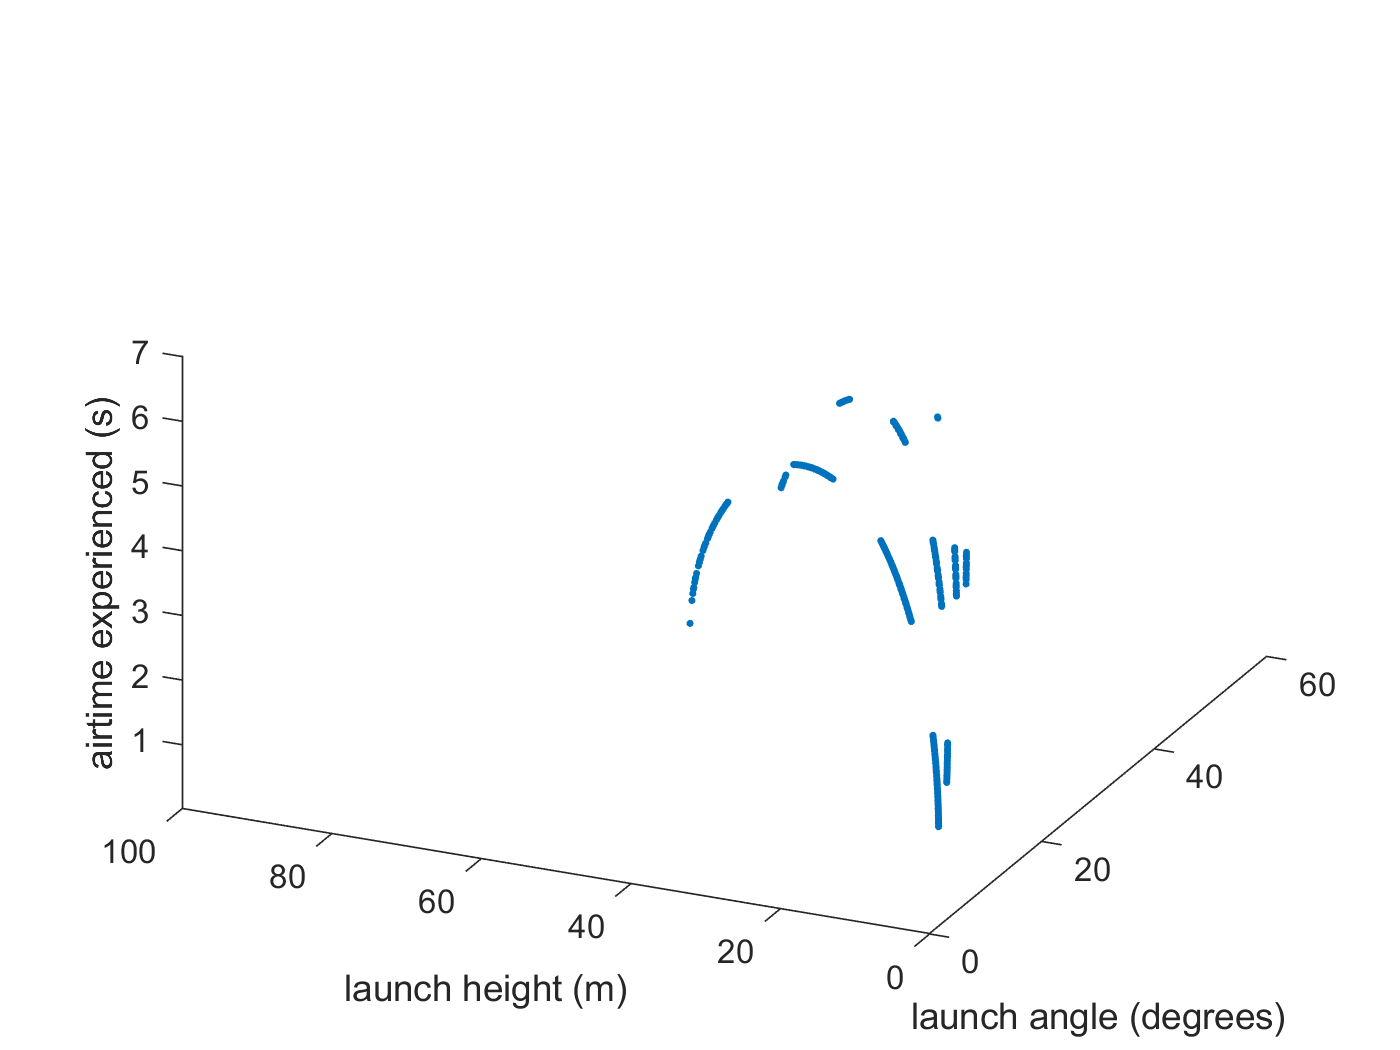

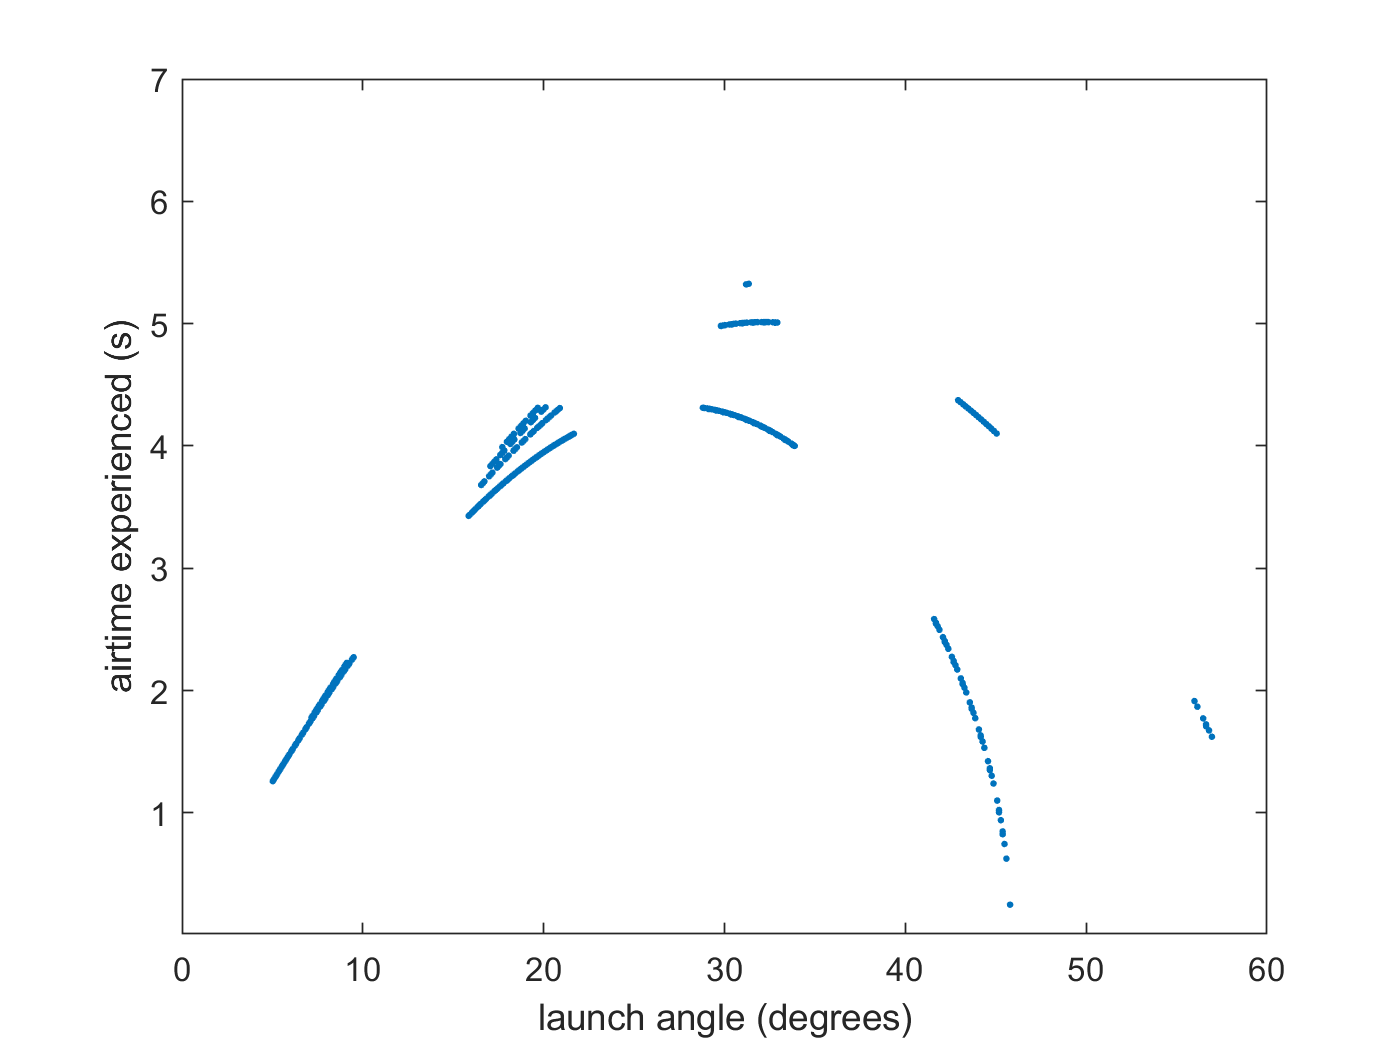

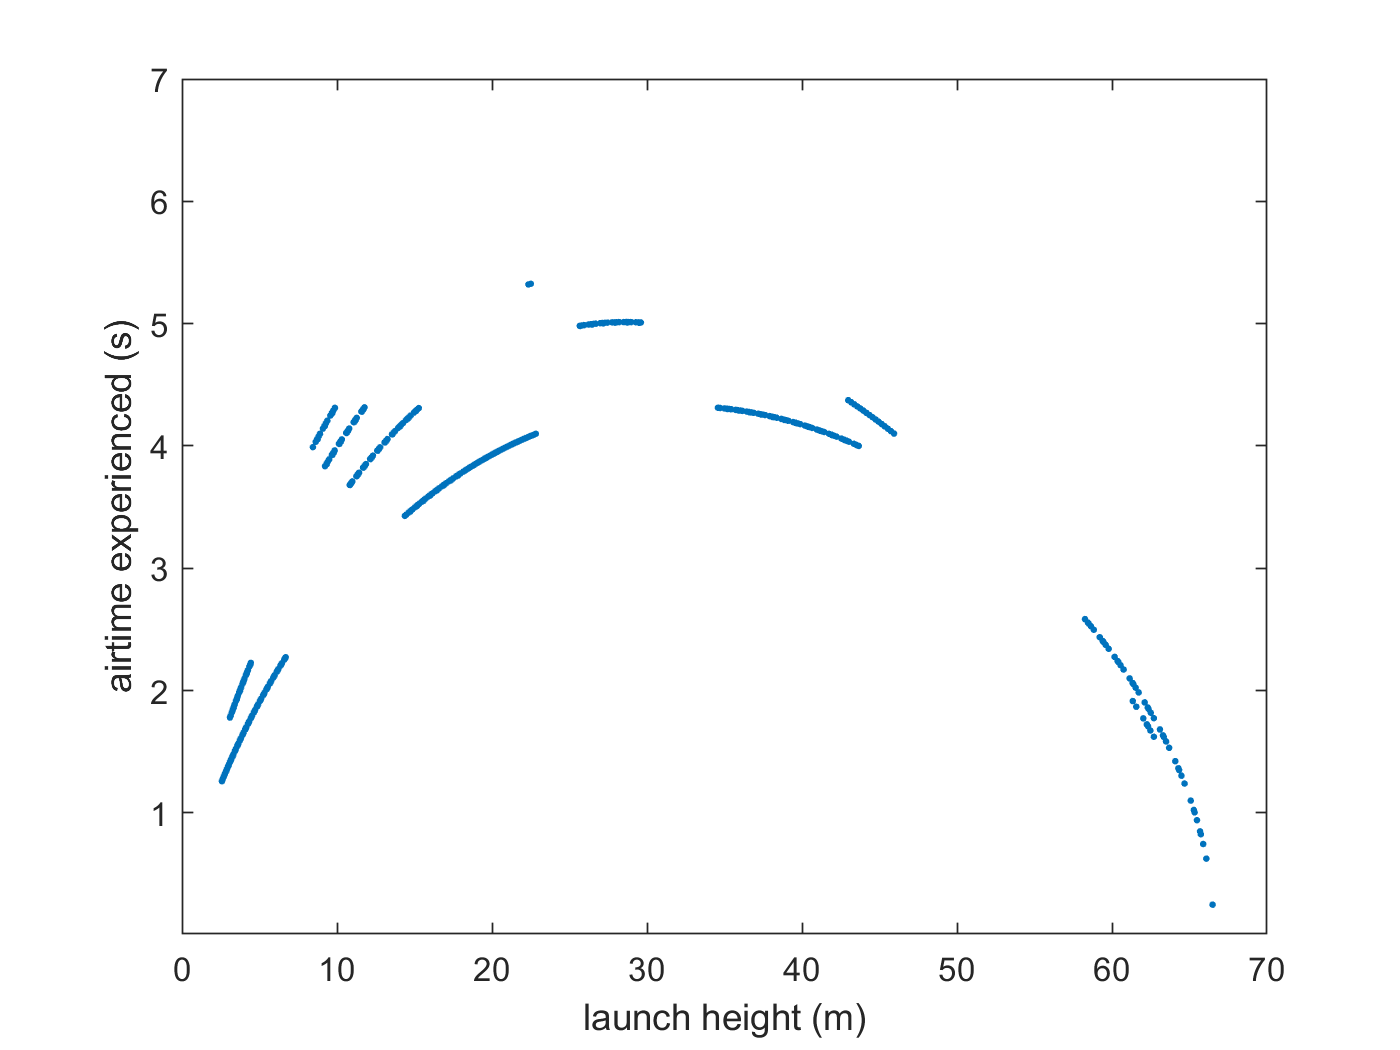

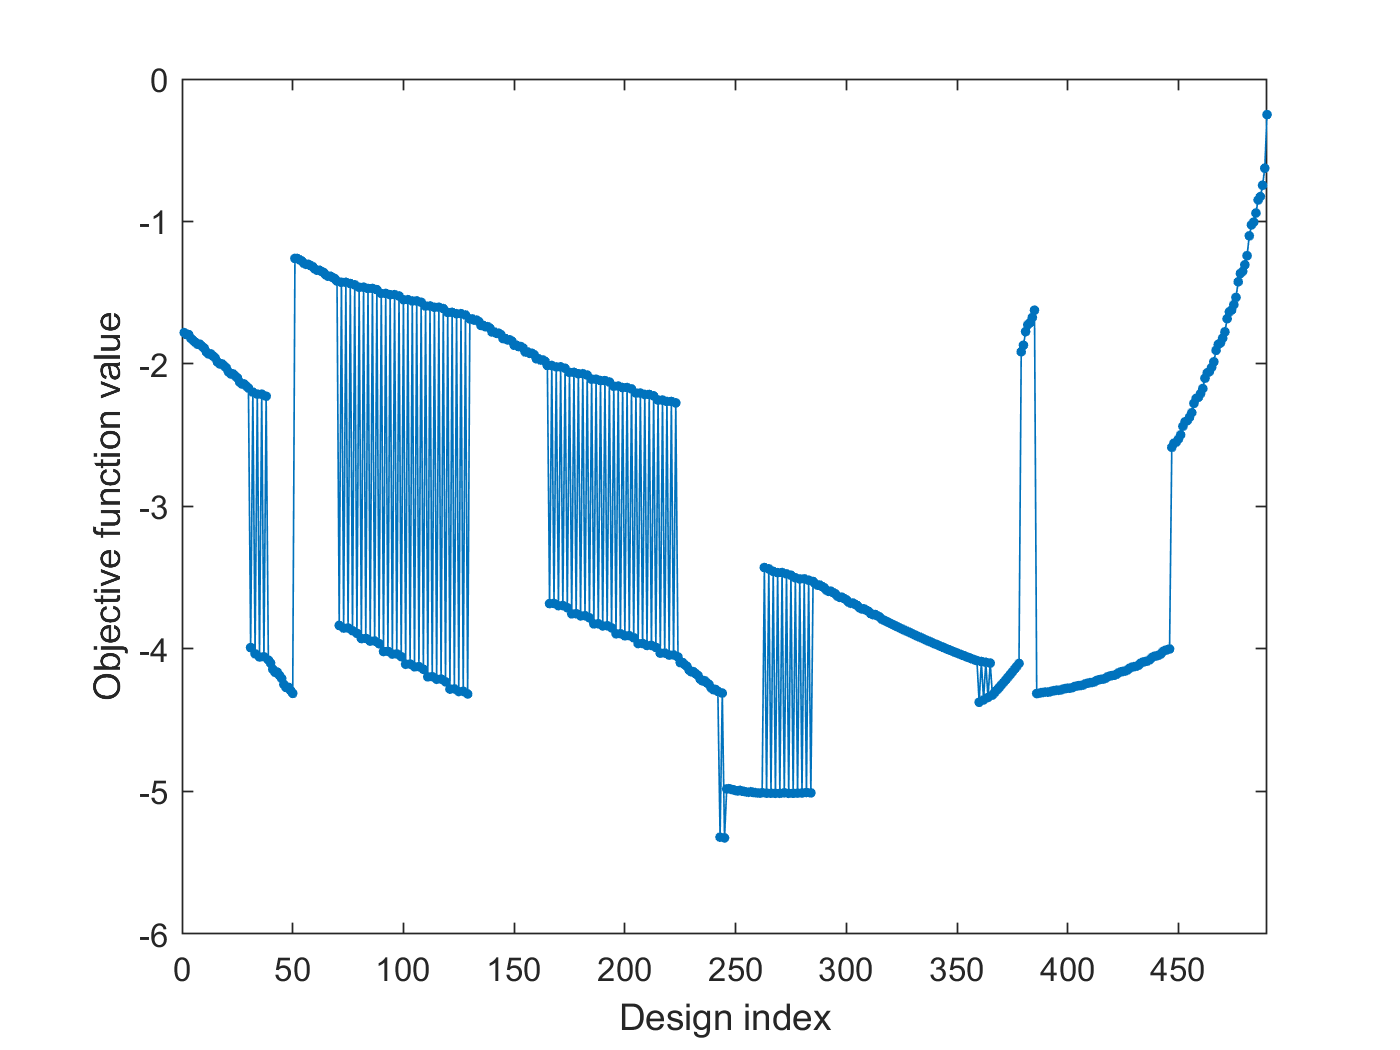

% Visualising relationships between design variables in this model
objectiveVisualization

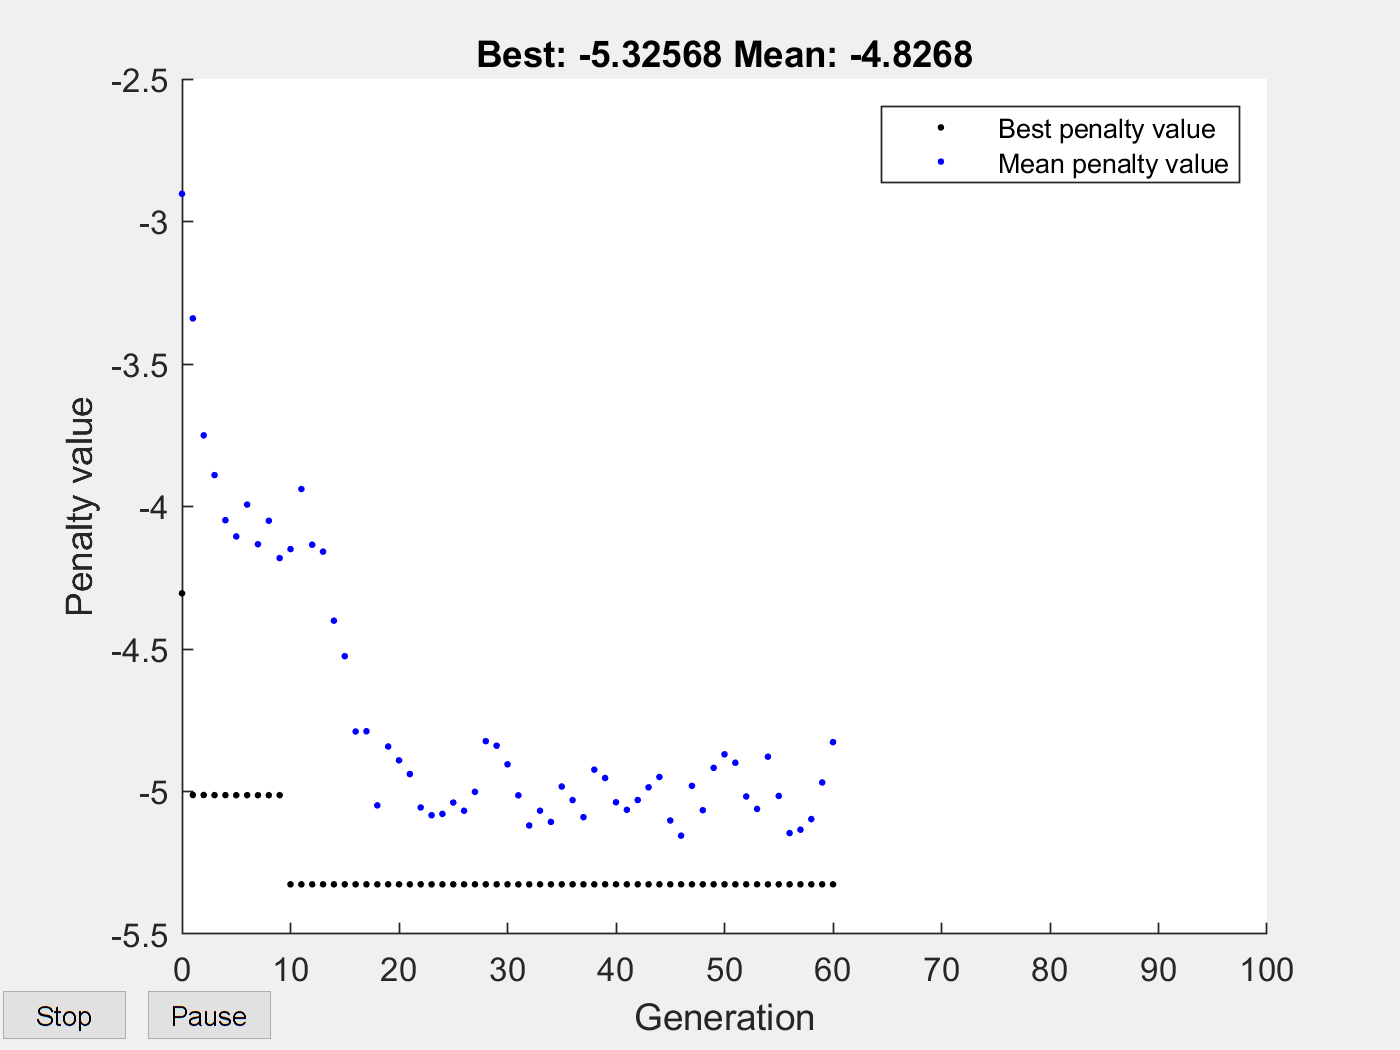


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1               80          -5.012           -3.34        0
    2              118          -5.012           -3.75        1
    3              156          -5.013           -3.89        0
    4              194          -5.013          -4.048        1
    5              232          -5.013          -4.105        2
    6              270          -5.013          -3.993        3
    7              308          -5.013          -4.132        4
    8              346          -5.013           -4.05        5
    9              384          -5.013          -4.181        6
   10              422          -5.326          -4.149        0
   11              460          -5.326          -3.939        1
   12              498          -5.326          -4.134        2
   13              536          -5.326          -4.158        3
   14              574        

x = 245

fval = -5.3257

exitflag = 1

output = struct with fields:
      problemtype: 'integerconstraints'
         rngstate: [1×1 struct]
      generations: 60
        funccount: 2323
          message: 'Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance↵and constraint violation is less than options.ConstraintTolerance.'
    maxconstraint: 0


population =    245
   245
   245
   205
   245
   245
   245
   245
   245
   245


scores =    -5.3257
   -5.3257
   -5.3257
   -2.2043
   -5.3257
   -5.3257
   -5.3257
   -5.3257
   -5.3257
   -5.3257


Elapsed time is 9.715703 seconds.


airtime = 5.3257

length = 85.4000

height = 22.5043

angle = 31.3399

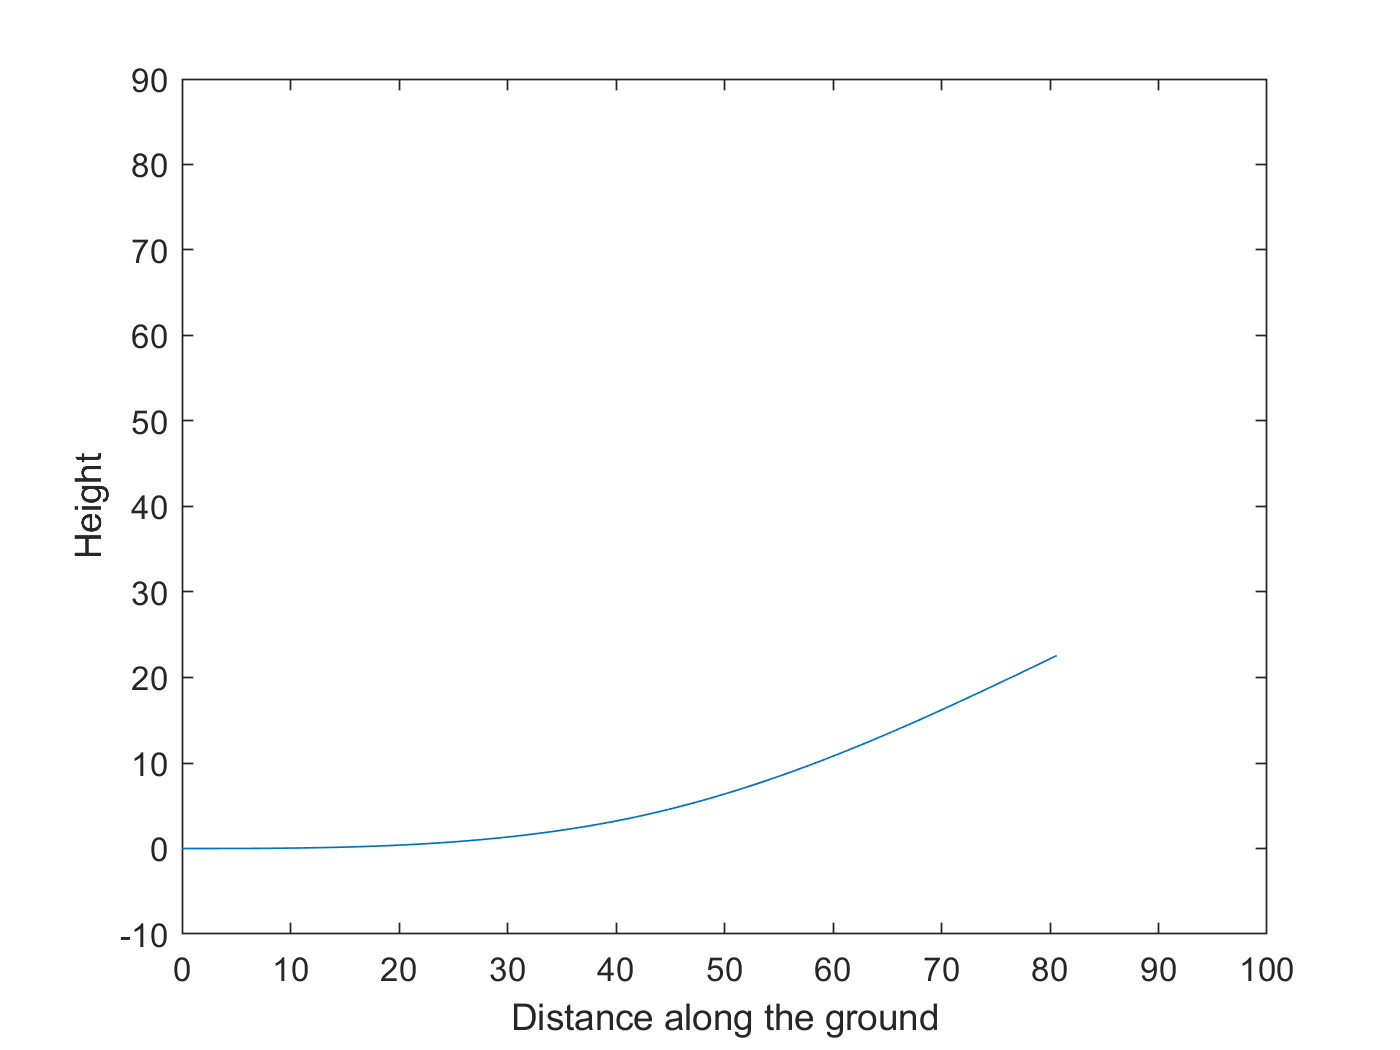

% Optimisation using a Genetic Algorithm, and visualisation of optimal
% launch track shape
geneticAlgorithm

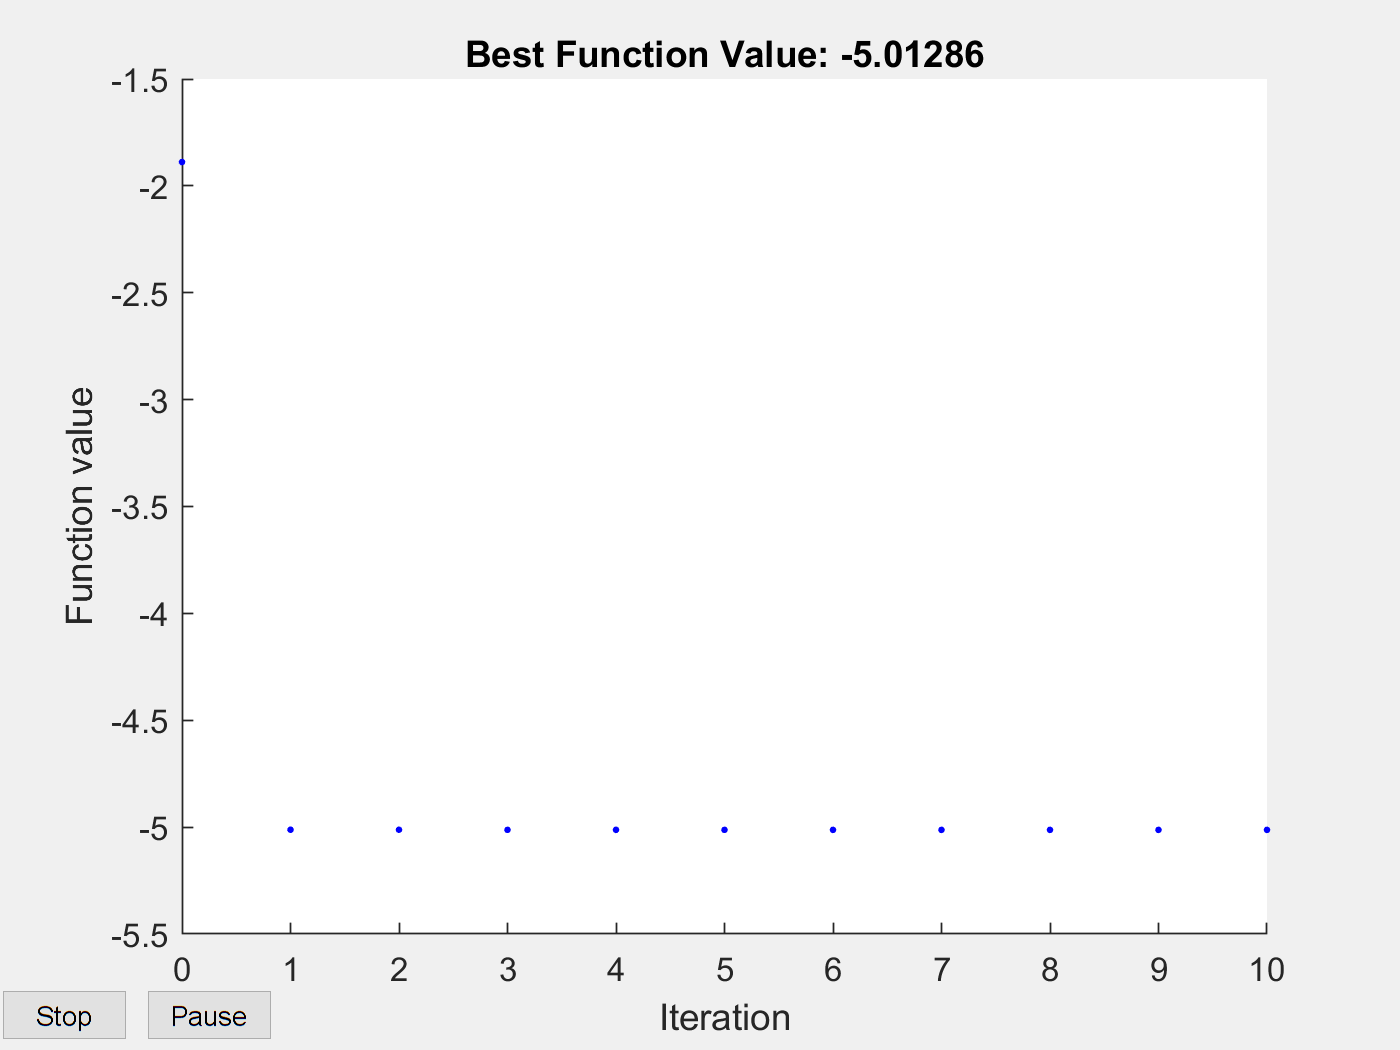



Iter     Func-count       f(x)      MeshSize     Method
    0           1       -1.88841           256      
    1           3       -5.01229             1     Successful Poll
    2           5       -5.01229          0.25     Refine Mesh
    3           7       -5.01272             1     Successful Poll
    4           9       -5.01272          0.25     Refine Mesh
    5          11       -5.01272        0.0625     Refine Mesh
    6          14       -5.01286          0.25     Successful Poll
    7          16       -5.01286        0.0625     Refine Mesh
    8          18       -5.01286       0.01563     Refine Mesh
    9          20       -5.01286      0.003906     Refine Mesh
   10          22       -5.01286     0.0009766     Refine Mesh


Array indices must be positive integers or logical values.

Error in obj (line 13)
    fitness = -(2*sin((launchAngles(index)*2*pi/180))*sqrt(u^2 - 2*g*launchHeights(index)))/g;

Error in funevaluate (line 40)
    f = feval(FUN,reshapeinput(Xin,X),varargin{:});

Error

% Optimisation attempt using a Pattern Search algorithm. Will yield an
% indexing error due at small mesh sizes.
patternSearch